clearvars;

N = 5000; % Number of points
t = linspace(0,5,N)'; % Time vector with fs = 500 Hz

a= 0.75;
phi = 0;
snr = 10;

s = sawtooth(2*pi*2*t(1:N,1),0.5); % Sawtooth signal
n1 = 0.2*sin(2*pi*50*t(1:N/2,1)-phi); % Sinusoid at 50 Hz
n2 = 0.3*sin(2* pi*100*t(N/2+1:N,1)-phi); % Sinusoid at 100 Hz
nwg = s - awgn(s,snr,'measured'); % Gaussian white noise

r = (nwg + [n1 ;n2])*a;
x = s+nwg + [n1 ;n2];

delta = 1e-3;
lambdas = linspace(0.5,0.99,20);
errors_Matrix_RLS = zeros(length(3:15),20);

best_M_RLS = 0;
best_lambda = 0;
best_constructed_signal_RLS = [];
minimum_sqr_error = inf;

k=0;
for M = 3:15
    k = k+1;
    for l = 1:20
        lambda = lambdas(l);

        p_n = ((lambda)^(-1))*eye(M);
        w_n = rand(M,1);
        % w_n = zeros(M,1);
        constructed_signal_RLS = [];

        for h = 1:length(x)-M+1
            R = r(h:h+M-1);

            k_n = ((lambda^-1)*p_n*R) / (1 + (lambda^-1)*R'*p_n*R);
            p_n = (lambda^-1)*p_n - (lambda^-1)*k_n*R'*p_n;
            alpha_n = x(h+M-1) - w_n'*R;
            w_n = w_n + k_n*alpha_n;
            constructed_signal_RLS = [constructed_signal_RLS; alpha_n];
        end
        
        sqr_error = sum((x(M:end)-constructed_signal_RLS).^2);
        errors_Matrix_RLS(k,l) = sqr_error;

        if sqr_error < minimum_sqr_error
            best_M_RLS = M;
            best_lambda = lambda;
            best_constructed_signal_RLS = constructed_signal_RLS;
            minimum_sqr_error = sqr_error;
        end
    end
end

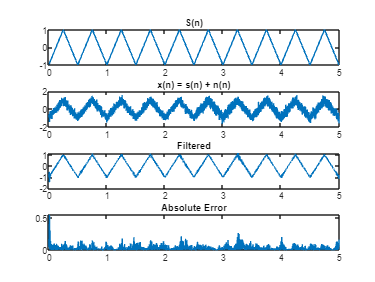

figure('Position', [100, 100, 800, 600]);
subplot(4, 1, 1); 
plot(t(best_M_RLS:end), s(best_M_RLS:end));
title("S(n)")

subplot(4, 1, 2); 
plot(t(best_M_RLS:end), x(best_M_RLS:end));
title("x(n) = s(n) + n(n)");

subplot(4, 1, 3); 
plot(t(best_M_RLS:end),best_constructed_signal_RLS);
title("Filtered");

subplot(4, 1, 4); 
plot(t(best_M_RLS:end), abs(s(best_M_RLS:end)-best_constructed_signal_RLS));
title("Absolute Error");

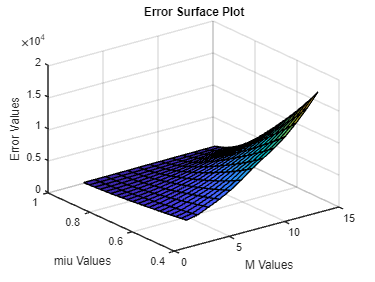

figure;
[M, Lambda] = meshgrid(3:15, lambdas);
surf(M, Lambda, errors_Matrix_RLS');

xlabel('M Values');
ylabel('miu Values');
zlabel('Error Values');
title('Error Surface Plot');
view(3);